clear
waveform = phased.LinearFMWaveform('PulseWidth',1e-4,'PRF',5e3,...
            'SampleRate',1e6,'OutputFormat','Pulses','NumPulses',1,...
            'SweepBandwidth',1e5);
        
wav = getMatchedFilter(waveform);

inputSignal = waveform();

taylorfilter = phased.MatchedFilter('Coefficients',wav,...
               'SpectrumWindow','Taylor');
           


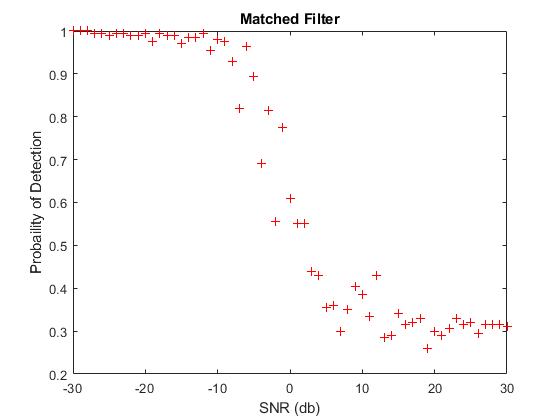

mySNR = -30:30;
find_PD_MF(10,mySNR)

function find_PD_MF(threshold,snr)
    waveform = phased.LinearFMWaveform('PulseWidth',1e-4,'PRF',5e3,...
                'SampleRate',1e6,'OutputFormat','Pulses','NumPulses',1,...
                'SweepBandwidth',1e5);
            
    wav = getMatchedFilter(waveform);
    
    inputSignal = waveform();
    
    taylorfilter = phased.MatchedFilter('Coefficients',wav,...
                   'SpectrumWindow','Taylor');
               
    N= length(inputSignal);
    
    for i = 1:length(snr)
        filtredSignal_taylor = abs(taylorfilter(awgn(inputSignal,snr(i))));
        PD(100) = 0;
        for j=1:100
            highValue = filtredSignal_taylor > threshold;
            PD(j) = sum(highValue)/N;
        end
        Pd = sum(PD)/100;
        plot(snr(i),Pd,'r+');
        hold on
        title('Matched Filter')
        xlabel('SNR (db)')
        ylabel('Probaility of Detection')
    end
    hold off
end
